# Reference Area from Elevation Contour

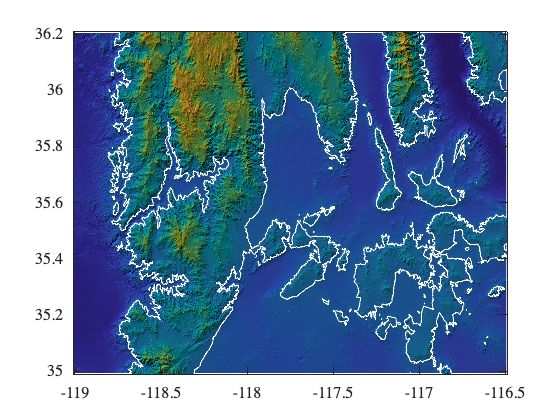

workdir= "/Volumes/Zel's Work Drive/Work/Ridgecrest";

referenceBelow= true;
elevationContour= 1000;


[LongLim,LatLim]= utils.loadBoundingBox(workdir);

% Load API key
APIfile= fullfile(workdir,"APIkey.txt");
if ~exist(APIfile,"file")
    error("API key not found in %s",APIfile)
end
APIkey= readlines(APIfile,'EmptyLineRule','skip');


grid= utils.createGrid(LatLim+ .01*[-1 1],LongLim+ .01*[-1 1],1/1200);

if ~exist("Elevation","var") || ~all(size(Elevation) == grid.Size)
    Elevation= utils.importSRTM90m(APIkey,grid.Lat,grid.Long);
    
    C= plt.toColorSimple(Elevation);
    illumination= plt.topographyShading(Elevation);
end

% Set the boundary either very high (if reference area is below the
% contour) or very low (if above), to get a closed contour
Elevation([1 2; end-1 end],:)= 1e6*(-1)^(referenceBelow+1);
Elevation(:,[1 2; end-1 end])= 1e6*(-1)^(referenceBelow+1);

[px,py]= plt.contourPolygon(grid.Long,grid.Lat,Elevation,elevationContour);

imagesc(grid.Long,grid.Lat,repmat(illumination,1,1,3).*C)
plt.pltOptions
hold on
plot(px,py,'Color',[1 1 1])
hold off

 

kmz.writeKMZPolygon(fullfile(workdir,"Google Earth","referenceArea.kmz"),px,py,"Reference Area");
